%% MODELO TOE (Triple Oscilador Entrelazado) - SIMULACIÓN DINÁMICA
% Autor: Kilian Hernández Cabrera
% Simulación de la evolución temporal de la Fidelidad F(t)

clear; clc; close all;

%% 1. PARÁMETROS DEL SISTEMA
hbar = 1;               % Unidades naturales
g = 1.0;                % Acoplamiento entre qutrits de dirección
w1 = 1.0; w2 = 1.0; w3 = 1.0; % Frecuencias libres de los osciladores
n_max = 3;              % Truncamiento de Fock por oscilador (0, 1, ..., n_max)

% Dimensiones de los subespacios
dim_q = 3;              % Qutrit (x, y, z)
dim_osc = n_max + 1;    % Oscilador armónico
dim_single = dim_q * dim_osc; % Dimensión por fuente (12)
dim_total = dim_single^3;     % Dimensión total (1728)

fprintf('Dimensión total del espacio de Hilbert truncado: %d\n', dim_total);

Dimensión total del espacio de Hilbert truncado: 1728


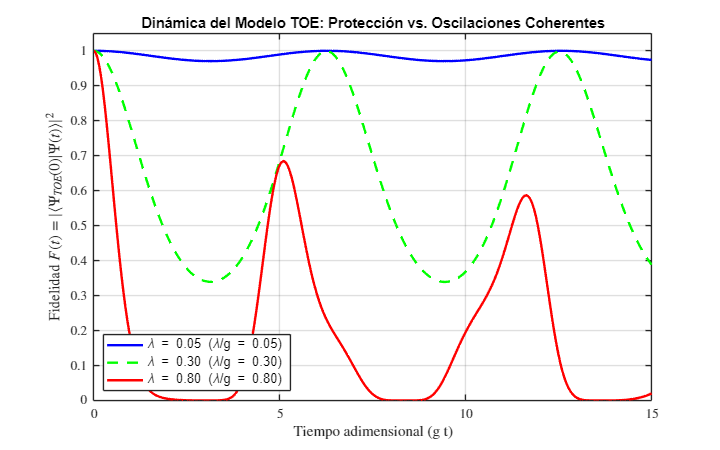

%% 2. OPERADORES BASE (Subespacios individuales)
% Qutrit: Operador cíclico X_hat (x=1, y=2, z=3)
X_q = [0 0 1; 
       1 0 0; 
       0 1 0]; 

% Oscilador: Operadores de aniquilación y creación
a_osc = zeros(dim_osc);
for n = 1:(dim_osc-1)
    a_osc(n, n+1) = sqrt(n);
end
adag_osc = a_osc';
N_osc = adag_osc * a_osc;

% Identidades
I_q = eye(dim_q);
I_osc = eye(dim_osc);
I_single = eye(dim_single);

%% 3. EXTENSIÓN A LAS 3 FUENTES (Espacio de Hilbert total)
% Operadores para cada fuente individual en el espacio total
% Fuente 1
X1 = kron(kron(X_q, I_osc), kron(I_single, I_single));
a1 = kron(kron(I_q, a_osc), kron(I_single, I_single));
adag1 = a1';
N1 = kron(kron(I_q, N_osc), kron(I_single, I_single));

% Fuente 2
X2 = kron(kron(I_single, kron(X_q, I_osc)), I_single);
a2 = kron(kron(I_single, kron(I_q, a_osc)), I_single);
adag2 = a2';
N2 = kron(kron(I_single, kron(I_q, N_osc)), I_single);

% Fuente 3
X3 = kron(I_single, kron(I_single, kron(X_q, I_osc)));
a3 = kron(I_single, kron(I_single, kron(I_q, a_osc)));
adag3 = a3';
N3 = kron(I_single, kron(I_single, kron(I_q, N_osc)));

%% 4. HAMILTONIANO INDEPENDIENTE DEL ACOPLAMIENTO (H_0 y H_int^dir)
% Hamiltoniano libre de los osciladores
H0 = hbar*w1*(N1 + 0.5*eye(dim_total)) + ...
     hbar*w2*(N2 + 0.5*eye(dim_total)) + ...
     hbar*w3*(N3 + 0.5*eye(dim_total));

% Hamiltoniano de interacción direccional entre qutrits
H_dir = (hbar * g / 2) * (X1*X2*X3 + X1'*X2'*X3');

%% 5. ESTADO INICIAL |Psi_TOE> x |0,0,0>
% Qutrits: 1/sqrt(3) * (|xyz> + |yzx> + |zxy>) -> |1,2,3>, |2,3,1>, |3,1,2>
psi_dir = zeros(dim_q^3, 1);
idx_xyz = (1-1)*9 + (2-1)*3 + 3; % |x,y,z>
idx_yzx = (2-1)*9 + (3-1)*3 + 1; % |y,z,x>
idx_zxy = (3-1)*9 + (1-1)*3 + 2; % |z,x,y>

psi_dir(idx_xyz) = 1/sqrt(3);
psi_dir(idx_yzx) = 1/sqrt(3);
psi_dir(idx_zxy) = 1/sqrt(3);

% Vacío vibracional |0,0,0>
vac_osc = zeros(dim_osc^3, 1);
vac_osc(1) = 1; % Estado |0> para los tres osciladores

% Reordenamiento al espacio entrelazado (Fuente 1 x Fuente 2 x Fuente 3)
% Teniendo en cuenta la estructura (q1 x osc1) x (q2 x osc2) x (q3 x osc3)
psi_0 = zeros(dim_total, 1);
% Construcción explícita del kets inicial
v_x = [1;0;0]; v_y = [0;1;0]; v_z = [0;0;1];
v_0 = zeros(dim_osc, 1); v_0(1) = 1;

ket_xyz0 = kron(kron(kron(v_x,v_0), kron(v_y,v_0)), kron(v_z,v_0));
ket_yzx0 = kron(kron(kron(v_y,v_0), kron(v_z,v_0)), kron(v_x,v_0));
ket_zxy0 = kron(kron(kron(v_z,v_0), kron(v_x,v_0)), kron(v_y,v_0));

psi_0 = (1/sqrt(3)) * (ket_xyz0 + ket_yzx0 + ket_zxy0);

%% 6. SIMULACIÓN TEMPORAL PARA DISTINTOS ACOPLAMIENTOS (lambda)
t = linspace(0, 15, 300); % Malla de tiempo
lambdas = [0.05, 0.3, 0.8]; % Débil, intermedio, fuerte
color_lines = {'b-', 'g--', 'r-'};

figure('Color', [1 1 1], 'Position', [100 100 800 500]);
hold on; grid on; box on;

for k = 1:length(lambdas)
    lambda = lambdas(k);
    
    % Hamiltoniano oscilador-dirección
    H_osc_dir = hbar * lambda * (X1*adag1 + X1'*a1 + ...
                                 X2*adag2 + X2'*a2 + ...
                                 X3*adag3 + X3'*a3);
                             
    % Hamiltoniano Total
    H_total = H0 + H_dir + H_osc_dir;
    
    % Diagonalización para la evolución temporal: H = V * D * V'
    [V, D] = eig(H_total);
    diag_D = diag(D);
    
    % Proyección del estado inicial en la base propia
    c = V' * psi_0;
    
    % Fidelidad F(t) = |<psi_0|psi(t)>|^2
    F = zeros(size(t));
    for it = 1:length(t)
        psi_t = V * (c .* exp(-1i * diag_D * t(it) / hbar));
        F(it) = abs(psi_0' * psi_t)^2;
    end
    
    plot(t, F, color_lines{k}, 'LineWidth', 2, ...
        'DisplayName', sprintf('\\lambda = %.2f (\\lambda/g = %.2f)', lambda, lambda/g));
end

% Ajustes estéticos de la gráfica para publicación
xlabel('Tiempo adimensional (g t)', 'FontSize', 12, 'Interpreter', 'latex');
ylabel('Fidelidad $F(t) = |\langle \Psi_{TOE}(0) | \Psi(t) \rangle|^2$', 'FontSize', 12, 'Interpreter', 'latex');
title('Dinámica del Modelo TOE: Protección vs. Oscilaciones Coherentes', 'FontSize', 14);
ylim([0 1.05]);
legend('Location', 'southwest', 'FontSize', 11);
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);

%% 7. ANÁLISIS DE LA FRECUENCIA DE RABI
% Verificación numérica de Omega_Rabi = sqrt(g^2 + (2*lambda)^2)
lambda_test = 0.8;
Omega_teorico = sqrt(g^2 + (2*lambda_test)^2);
fprintf('\n--- Verificación Teórica ---');


--- Verificación Teórica ---

fprintf('\nPara lambda = %.2f, g = %.2f:', lambda_test, g);


Para lambda = 0.80, g = 1.00:

fprintf('\nFrecuencia teórica de Rabi (efectiva): %.4f rad/s\n', Omega_teorico);


Frecuencia teórica de Rabi (efectiva): 1.8868 rad/s


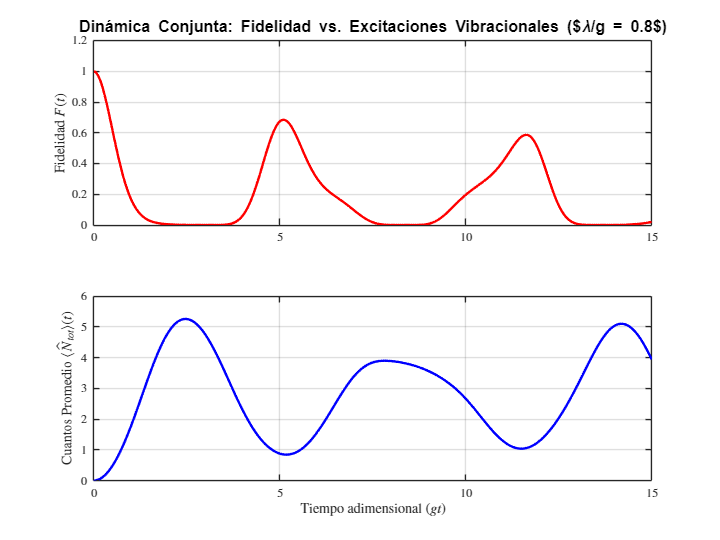


%% MUESTRA DE POBLACIÓN DE CUANTOS <N(t)> Y FIDELIDAD
% Añadir dentro del bucle de simulación temporal:

% Operador número total de cuantos: N_total = N1 + N2 + N3
N_tot = N1 + N2 + N3;

% En el bucle temporal it:
N_avg = zeros(size(t));
for it = 1:length(t)
    psi_t = V * (c .* exp(-1i * diag_D * t(it) / hbar));
    F(it) = abs(psi_0' * psi_t)^2;
    N_avg(it) = real(psi_t' * N_tot * psi_t); % Cuantos promedio totales
end

% Gráfica comparativa de 2 paneles
figure('Color', [1 1 1], 'Position', [100 100 800 600]);

subplot(2,1,1);
plot(t, F, 'r-', 'LineWidth', 2);
ylabel('Fidelidad $F(t)$', 'Interpreter', 'latex', 'FontSize', 12);
title('Dinámica Conjunta: Fidelidad vs. Excitaciones Vibracionales ($\lambda/g = 0.8$)', 'FontSize', 13);
grid on; set(gca, 'TickLabelInterpreter', 'latex');

subplot(2,1,2);
plot(t, N_avg, 'b-', 'LineWidth', 2);
xlabel('Tiempo adimensional ($g t$)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Cuantos Promedio $\langle \hat{N}_{tot} \rangle(t)$', 'Interpreter', 'latex', 'FontSize', 12);
grid on; set(gca, 'TickLabelInterpreter', 'latex');